# Support Vector Machine vs. Random Forest Classifier Evaluation

Đánh giá và so sánh mô hình SVM (RBF Kernel) và Random Forest trên bộ đặc trưng dung hợp (Hình thái + Màu sắc HSV + Kết cấu GLCM).

## 1. ĐÁNH GIÁ CÁC MÔ HÌNH HỌC MÁY (EVALUATION)


if exist('../reports', 'dir')
    addpath('../reports');
elseif exist('reports', 'dir')
    addpath('reports');
end

% Nạp kết quả dự đoán (Y_test gốc và predictions của các mô hình)
load('fusion_results.mat'); % Chứa: Y_test, predictions_fusion (1: SVM, 2: RF)
load('bovw_results.mat');   % Chứa: predictions_bovw (1: SVM, 2: RF)

disp('✅ Đã nạp thành công dữ liệu dự đoán của hệ Fusion và BoVW!');

✅ Đã nạp thành công dữ liệu dự đoán của hệ Fusion và BoVW!


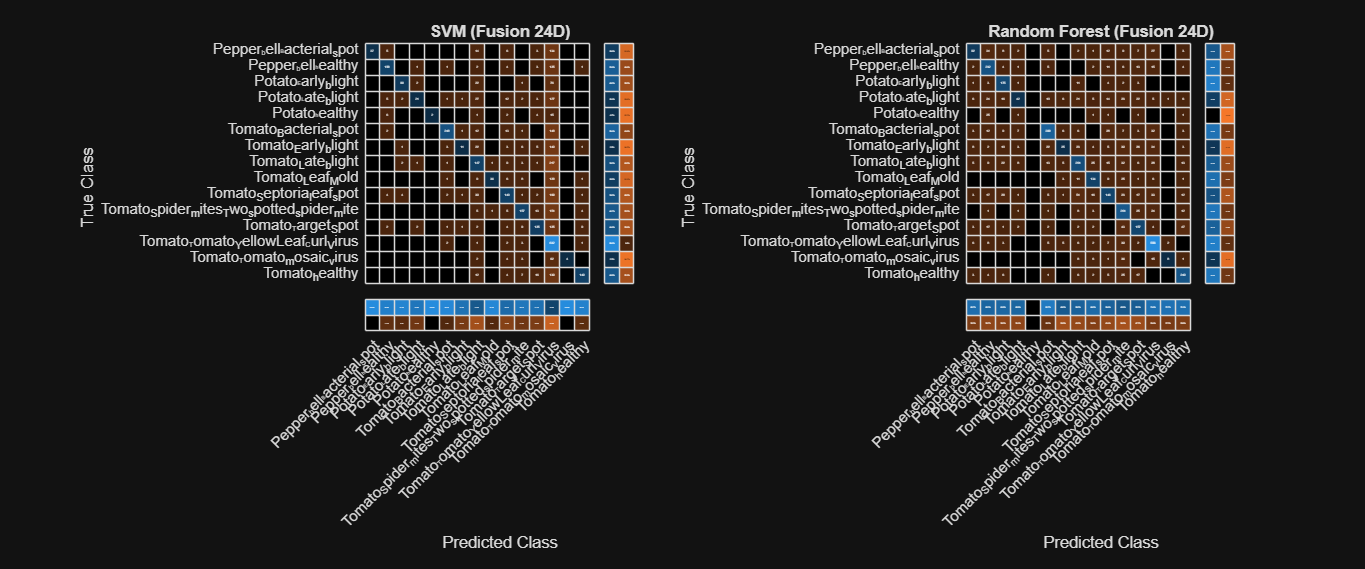


% 2.1. Ma trận nhầm lẫn cho hệ FUSION (Đặc trưng Hình thái + HSV + GLCM)
figure('Name', 'Confusion Matrix - Fusion Features', 'Position', [100, 100, 1200, 500]);
subplot(1,2,1);
cm_svm_fusion = confusionchart(Y_test, predictions_fusion{1}, 'Title', 'SVM (Fusion 24D)');
cm_svm_fusion.RowSummary = 'row-normalized'; % Hiển thị Recall/True Positive Rate
cm_svm_fusion.ColumnSummary = 'column-normalized'; % Hiển thị Precision

subplot(1,2,2);
cm_rf_fusion = confusionchart(Y_test, predictions_fusion{2}, 'Title', 'Random Forest (Fusion 24D)');
cm_rf_fusion.RowSummary = 'row-normalized';
cm_rf_fusion.ColumnSummary = 'column-normalized';

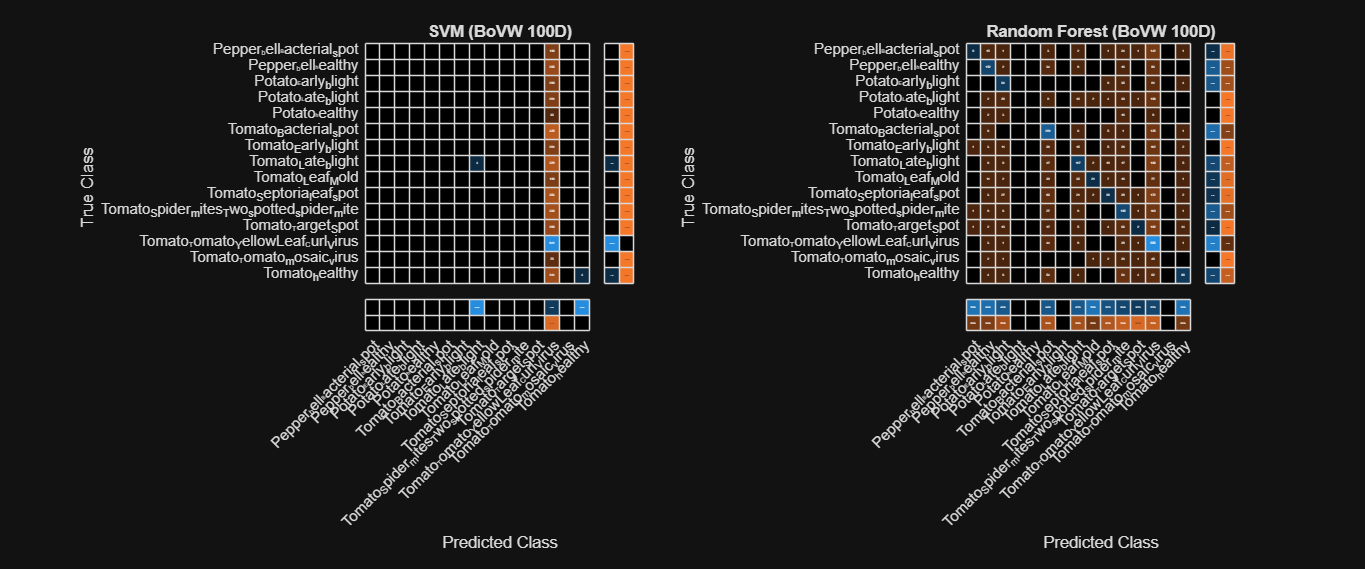

% 2.2. Ma trận nhầm lẫn cho hệ BoVW (Đặc trưng Cục bộ)
figure('Name', 'Confusion Matrix - BoVW Features', 'Position', [100, 100, 1200, 500]);
subplot(1,2,1);
cm_svm_bovw = confusionchart(Y_test, predictions_bovw{1}, 'Title', 'SVM (BoVW 100D)');
cm_svm_bovw.RowSummary = 'row-normalized';
cm_svm_bovw.ColumnSummary = 'column-normalized';

subplot(1,2,2);
cm_rf_bovw = confusionchart(Y_test, predictions_bovw{2}, 'Title', 'Random Forest (BoVW 100D)');
cm_rf_bovw.RowSummary = 'row-normalized';
cm_rf_bovw.ColumnSummary = 'column-normalized';

all_predictions = {predictions_fusion{1}, predictions_fusion{2}, ...
    predictions_bovw{1}, predictions_bovw{2}};
model_names = {'SVM (Fusion)', 'RF (Fusion)', 'SVM (BoVW)', 'RF (BoVW)'};

% Khởi tạo ma trận lưu kết quả: [Accuracy, Precision, Recall, F1_Score]
metrics_results = zeros(4, 4);

for i = 1:4
    pred = all_predictions{i};

    % Tính Confusion Matrix dạng số
    C = confusionmat(Y_test, pred);

    % Tổng số mẫu
    total_samples = sum(C(:));
    % Tính True Positives (Đường chéo)
    TP = diag(C);

    % Tổng theo hàng (Thực tế) và cột (Dự đoán)
    actual_counts = sum(C, 2);
    predicted_counts = sum(C, 1)';

    % Tính toán Metrics (Macro-average cho Multi-class)
    Accuracy = sum(TP) / total_samples;

    % Bỏ qua phép chia cho 0 bằng hàm 'omitnan'
    Precision = mean(TP ./ predicted_counts, 'omitnan'); 
    Recall = mean(TP ./ actual_counts, 'omitnan');
    F1_Score = 2 * (Precision * Recall) / (Precision + Recall);

    % Lưu vào mảng
    metrics_results(i, :) = [Accuracy, Precision, Recall, F1_Score];
end

% Hiển thị Bảng kết quả ra màn hình Live Script
ResultsTable = array2table(metrics_results, ...
    'VariableNames', {'Accuracy', 'Precision', 'Recall', 'F1_Score'}, ...
    'RowNames', model_names);

disp('--- BẢNG TỔNG HỢP KẾT QUẢ ĐÁNH GIÁ MÔ HÌNH ---');

--- BẢNG TỔNG HỢP KẾT QUẢ ĐÁNH GIÁ MÔ HÌNH ---


disp(ResultsTable);

                    Accuracy    Precision     Recall     F1_Score
                    ________    _________    ________    ________

    SVM (Fusion)    0.47638      0.79872      0.36115    0.49739 
    RF (Fusion)     0.62685      0.62509      0.52817    0.57256 
    SVM (BoVW)      0.15726      0.71854     0.068203    0.12458 
    RF (BoVW)       0.36709      0.49454      0.25583    0.33722 



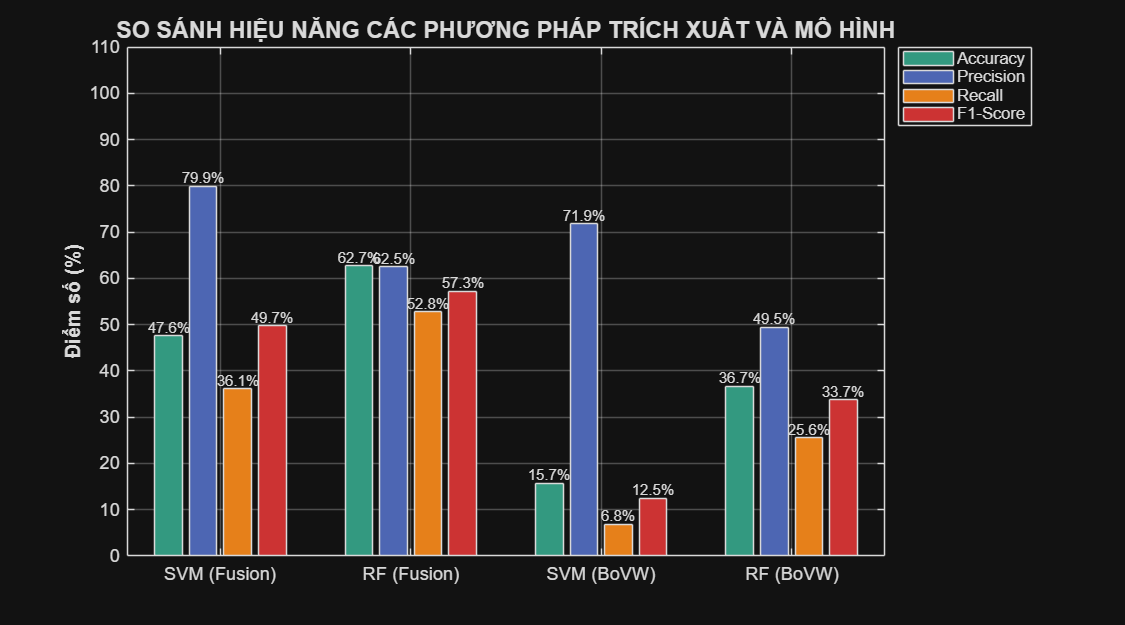

figure('Name', 'Model Comparison', 'Position', [200, 200, 900, 500]);
b = bar(metrics_results * 100); % Nhân 100 để hiển thị %
b(1).FaceColor = [0.2 0.6 0.5]; % Xanh lá (Accuracy)
b(2).FaceColor = [0.3 0.4 0.7]; % Xanh dương (Precision)
b(3).FaceColor = [0.9 0.5 0.1]; % Cam (Recall)
b(4).FaceColor = [0.8 0.2 0.2]; % Đỏ (F1-Score)

% Cấu hình trục và tiêu đề
set(gca, 'XTickLabel', model_names, 'FontSize', 11);
ylim([0 110]); % Để chừa khoảng trống cho nhãn số liệu bên trên
ylabel('Điểm số (%)', 'FontSize', 12, 'FontWeight', 'bold');
title('SO SÁNH HIỆU NĂNG CÁC PHƯƠNG PHÁP TRÍCH XUẤT VÀ MÔ HÌNH', 'FontSize', 14);
legend({'Accuracy', 'Precision', 'Recall', 'F1-Score'}, 'Location', 'northeastoutside');
grid on;

% Gắn nhãn số liệu trực tiếp lên đỉnh các cột
for i = 1:size(metrics_results, 2)
    xtips = b(i).XEndPoints;
    ytips = b(i).YEndPoints;
    labels = string(round(b(i).YData, 1)) + "%";
    text(xtips, ytips, labels, 'HorizontalAlignment', 'center', ...
        'VerticalAlignment', 'bottom', 'FontSize', 9);
end